% 方程 Uxx+Uyy=-4 边界值为0
f=@(x,y)4

f = 包含以下值的 function_handle :
    @(x,y)4


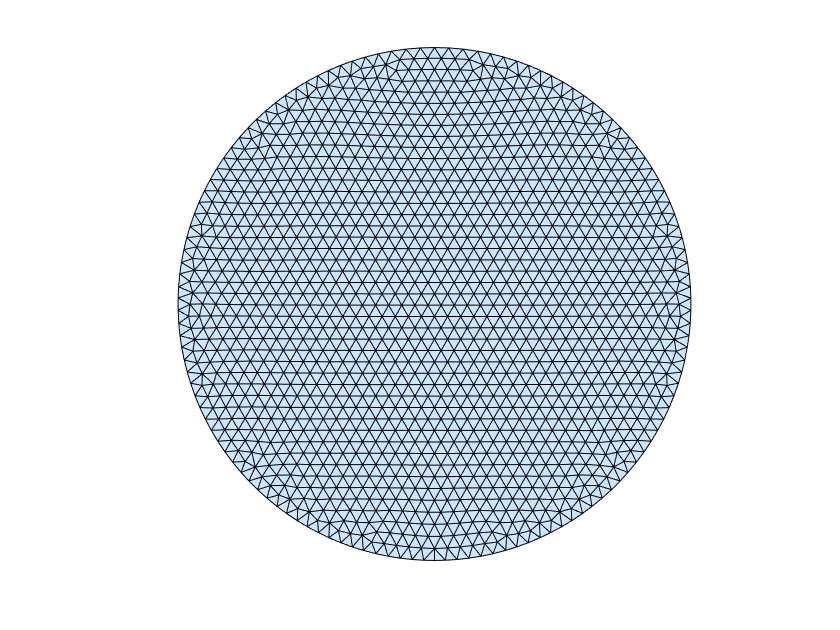

% 生成网格
fd=@(p) sqrt(sum(p.^2,2))-1; % 距离函数 确定所需要的区域
[p,t]=distmesh2d(fd,@huniform,0.05,[-1,-1;1,1],[]); % p 每个顶点的坐标 t(N*3) N个三角形对应的顶点标号

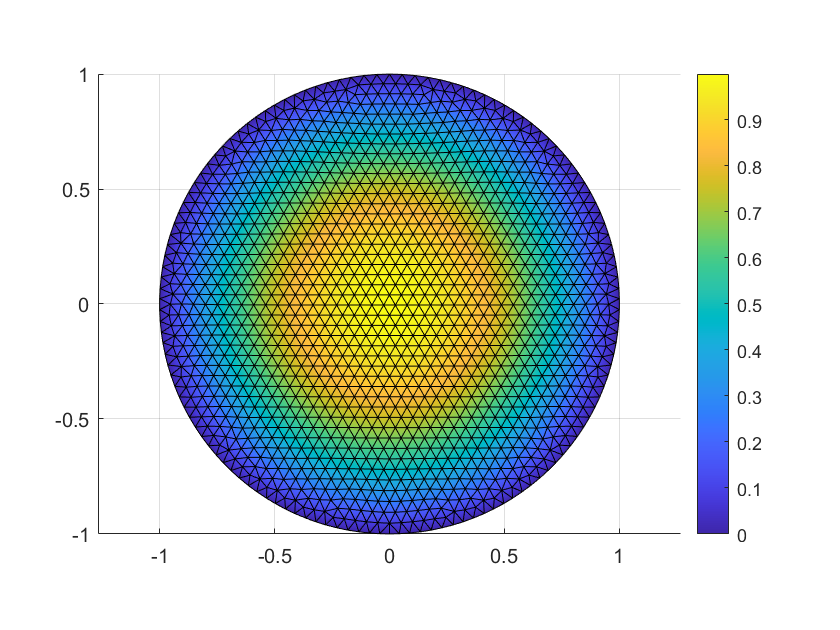

b=unique(boundedges(p,t)); % 边界对应的顶点们的序号

% 计算K F
N=size(p,1); % 节点数
T=size(t,1); % 三角形数
K=sparse(N,N); % 初始化为全零稀疏矩阵
F=zeros(N,1); % 全零

% 对每个三角形元计算 Fe Ke
for e=1:T
    nodes=t(e,:); % 所取三角形的三个节点序号
    Pe=[ones(3,1),p(nodes,:)]; % 2S=|Pe| 得到S的行列式
    S=abs(det(Pe))/2; % 求出 S 面积
    C=inv(Pe); % 求 a+bx+cy 中的系数 a b c 的时候有求逆
    
    % 计算 Ke 和 Fe
    grad=C(2:3,:); % B
    Ke=S*grad'*grad; % 计算 Ke
    Fe=S/3*4; % 这里刚好 f 是定值4
    % multiply Fe by f at centroid for load f(x,y): one-point quadrature!
    % centroid would be mean(p(nodes,:)) = average of 3 node coordinates
    
    % 更新到总刚度矩阵 K 和总荷载量 F
    K(nodes,nodes)=K(nodes,nodes)+Ke; 
    F(nodes)=F(nodes)+Fe;
end

% 添加边界条件
K(b,:)=0; K(:,b)=0; F(b)=0; % 将边界处的 K 和 F 设置为边界条件需要的0
K(b,b)=speye(length(b),length(b)); % 将 K 中的其他位置补充1

% 求解 U
U = K\F;

% 作图比较
trisurf(t,p(:,1),p(:,2),0*p(:,1),U,'edgecolor','k','facecolor','interp');
view(2),axis([-1 1 -1 1]),axis equal,colorbar


u = 1 - p(:,1).^2 - p(:,2).^2

u =    -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


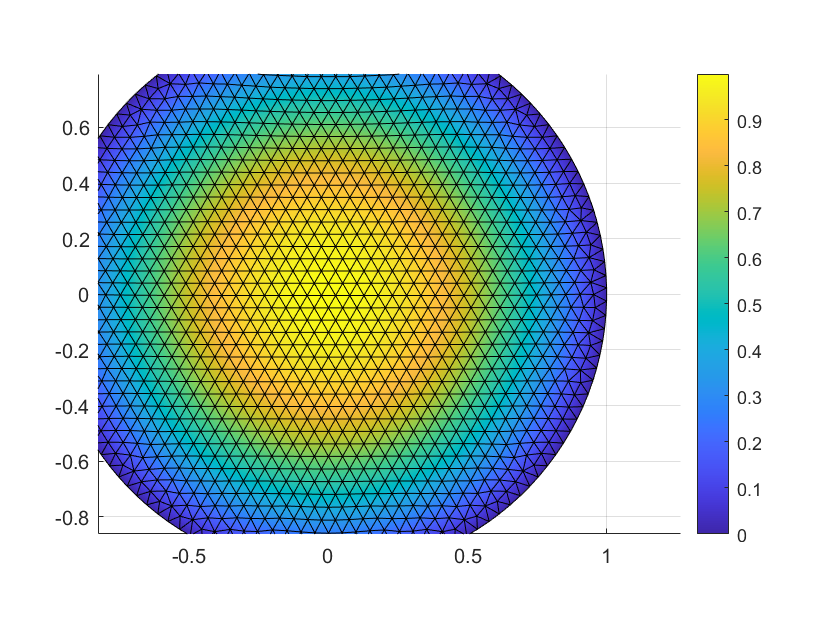

trisurf(t,p(:,1),p(:,2),0*p(:,1),u,'edgecolor','k','facecolor','interp');
view(2),axis([-1 1 -1 1]),axis equal,colorbar

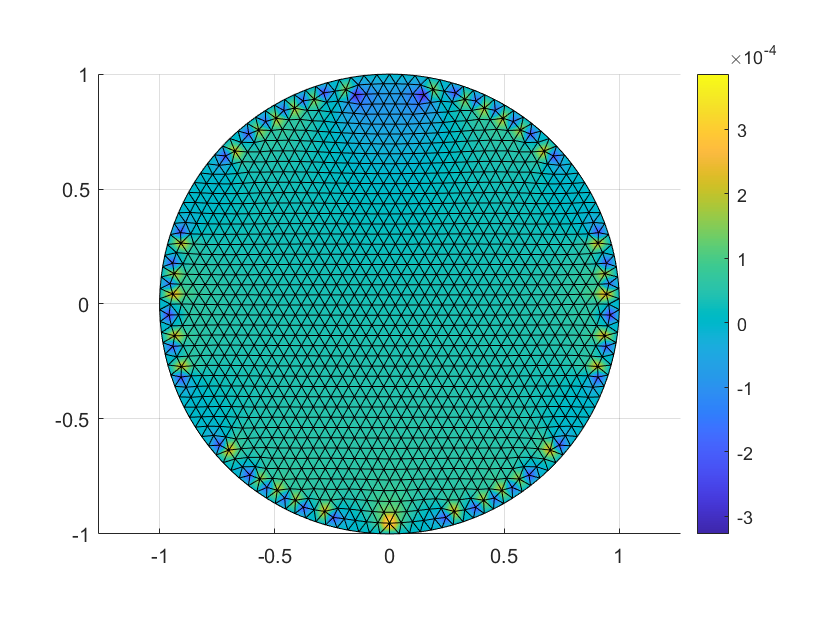


trisurf(t,p(:,1),p(:,2),0*p(:,1),U-u,'edgecolor','k','facecolor','interp');
view(2),axis([-1 1 -1 1]),axis equal,colorbar